# Missing data analysis

#### Background 

It is often necessary to to investigate any structure of missing observations in the data. For example, the missing data pattern could be (nearly) monotone. Monotonicity can be used to simplify the  imputation model (see Schafer 1997 for details). Also, the missing pattern could suggest which variables could potentially be useful for imputation of missing entries. 

Function [mdpattern](http://rosa.unipr.it/FSDA/mdpattern.html) of the FSDA provides a graphical summary of the outliers and a detailed report on the number of missing and univariate outliers for each variable.

## Example of use of function mdpattern

#### Example 1: the nhanes dataset

 The nhanes data is a dataset with 25 observations on the following 4 variables and is an example of non-monotone missing values.

   *age*, Age group (1=20-39, 2=40-59, 3=60+).

   *bmi*, Body mass index (kg/m^2).

  *hyp*, Hypertensive (1=no,2=yes).

   *chl*, Total serum cholesterol (mg/dL).

Table which shows missing values patterns
                   NrowsWithPattern    age    hyp    bmi    chl    NvarWithMis
                   ________________    ___    ___    ___    ___    ___________

    Pattern1              13            1      1      1      1          0     
    Pattern2               3            1      1      1      0          1     
    Pattern3               1            1      1      0      1          1     
    Pattern4               1            1      0      0      1          2     
    Pattern5               7            1      0      0      0          3     
    totPatOrMis           25            0      8      9     10         27     

0 means missing va

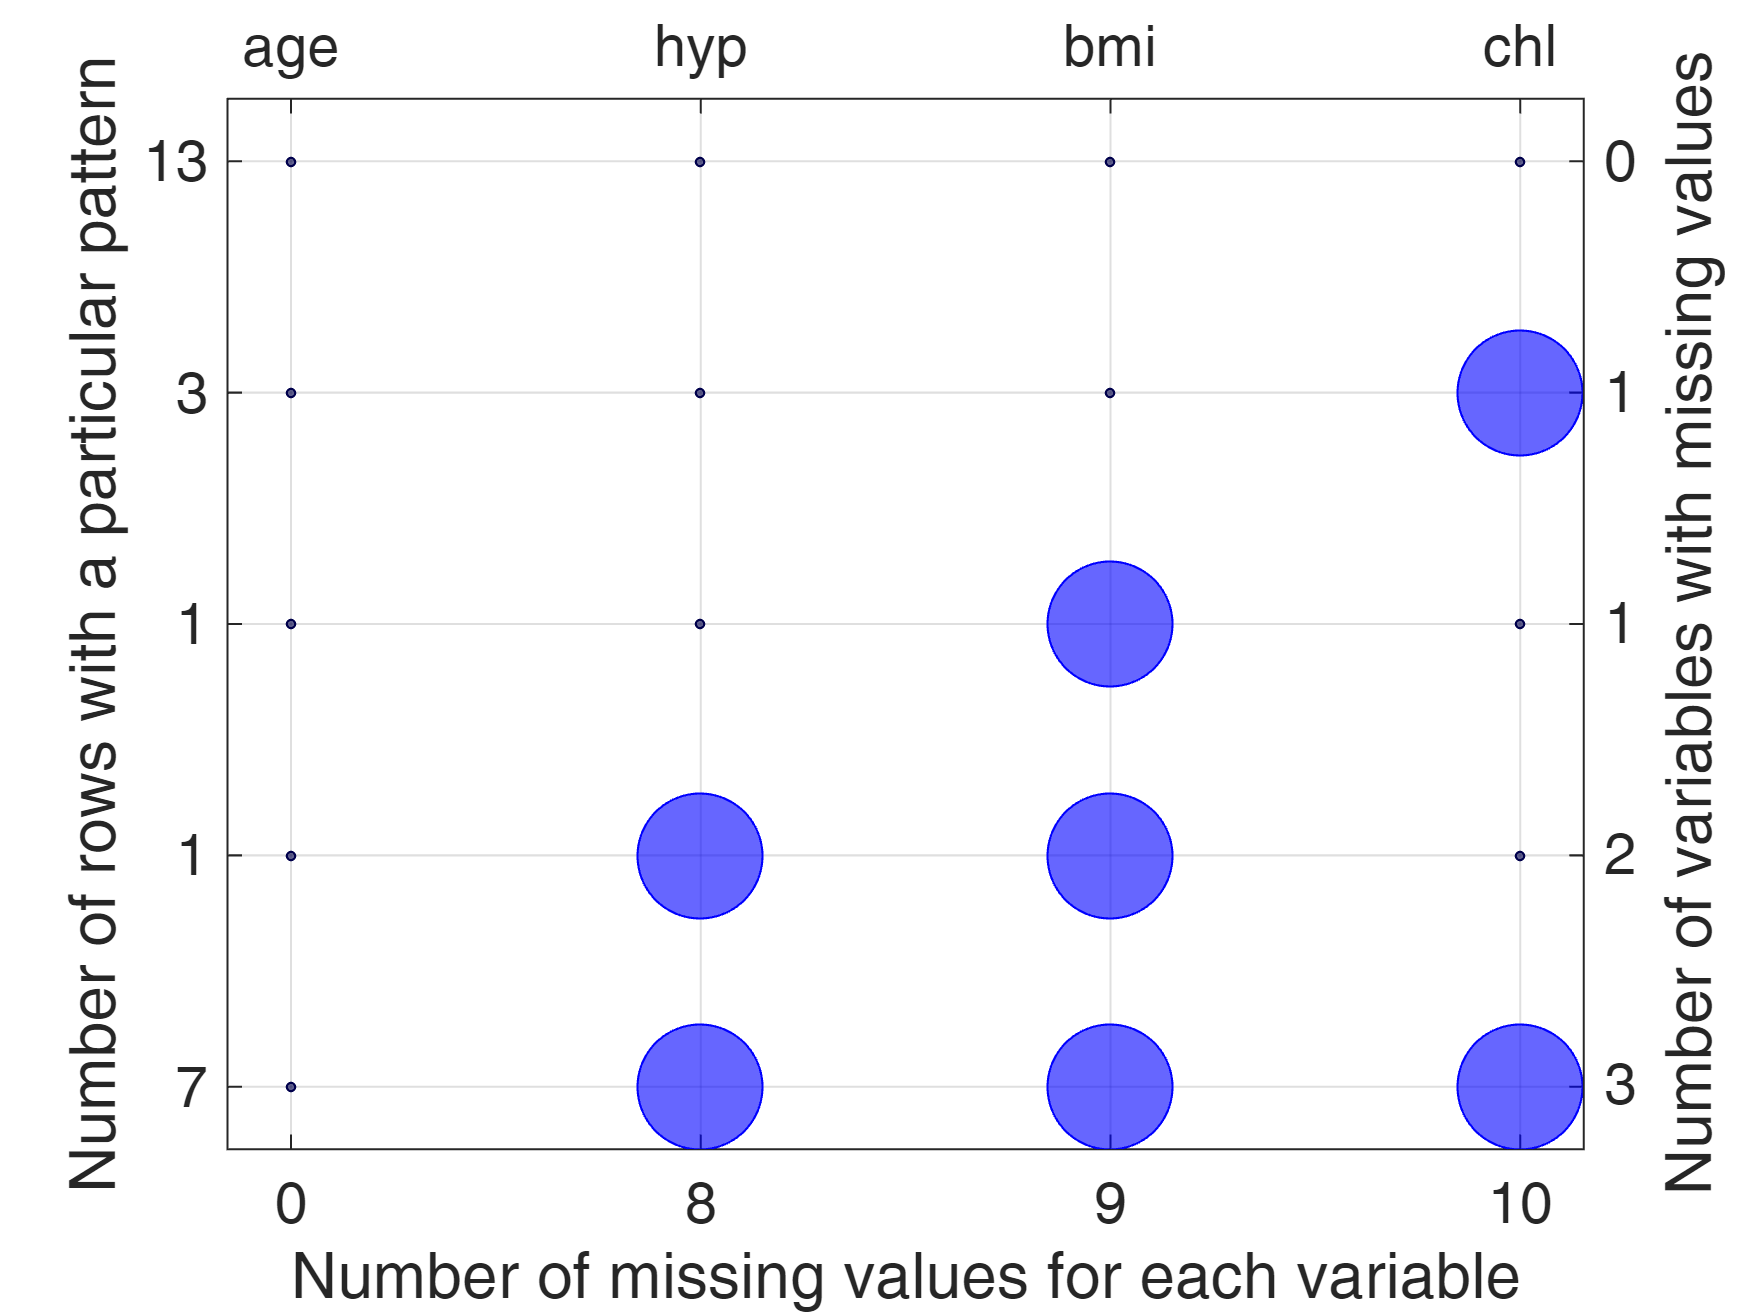

Detailed explanation of the "Missing data pattern figure"
Top axis contains the names of the variables.
Big circle means missing value; smaller filled dot represents non missing value.
Left axis shows the number of observations for each pattern
For example number 13 shows that the associated pattern is repeated 13 times.
The sum of the numbers on the left axis is n, the total number of rows.
Right axis counts the variables with missing values and
it is equal to the number of big circles in the corresponding row.
The number of missing values for each variable is shown on the bottom axis.


X=[1   NaN  NaN  NaN
    2 22.7   1 187
    1   NaN   1 187
    3   NaN  NaN  NaN
    1 20.4   1 113
    3   NaN  NaN 184
    1 22.5   1 118
    1 30.1   1 187
    2 22.0   1 238
    2   NaN  NaN  NaN
    1   NaN  NaN  NaN
    2   NaN  NaN  NaN
    3 21.7   1 206
    2 28.7   2 204
    1 29.6   1  NaN
    1   NaN  NaN  NaN
    3 27.2   2 284
    2 26.3   2 199
    1 35.3   1 218
    3 25.5   2  NaN
    1   NaN  NaN  NaN
    1 33.2   1 229
    1 27.5   1 131
    3 24.9   1  NaN
    2 27.4   1 186];
% namvar array of strings containing the names of the columns of X.
namvar=["age"  "bmi" "hyp" "chl"];
Xtable=array2table(X,VariableNames=namvar);
% option dispresults shows a detailed explanation of
% the content of two output tables in the command window.
dispresults=true;
[Mispat1,tMisAndOut1]=mdpattern(Xtable,'dispresults',dispresults);

#### Example 2: an example with 2 simulated patterns of missing values.

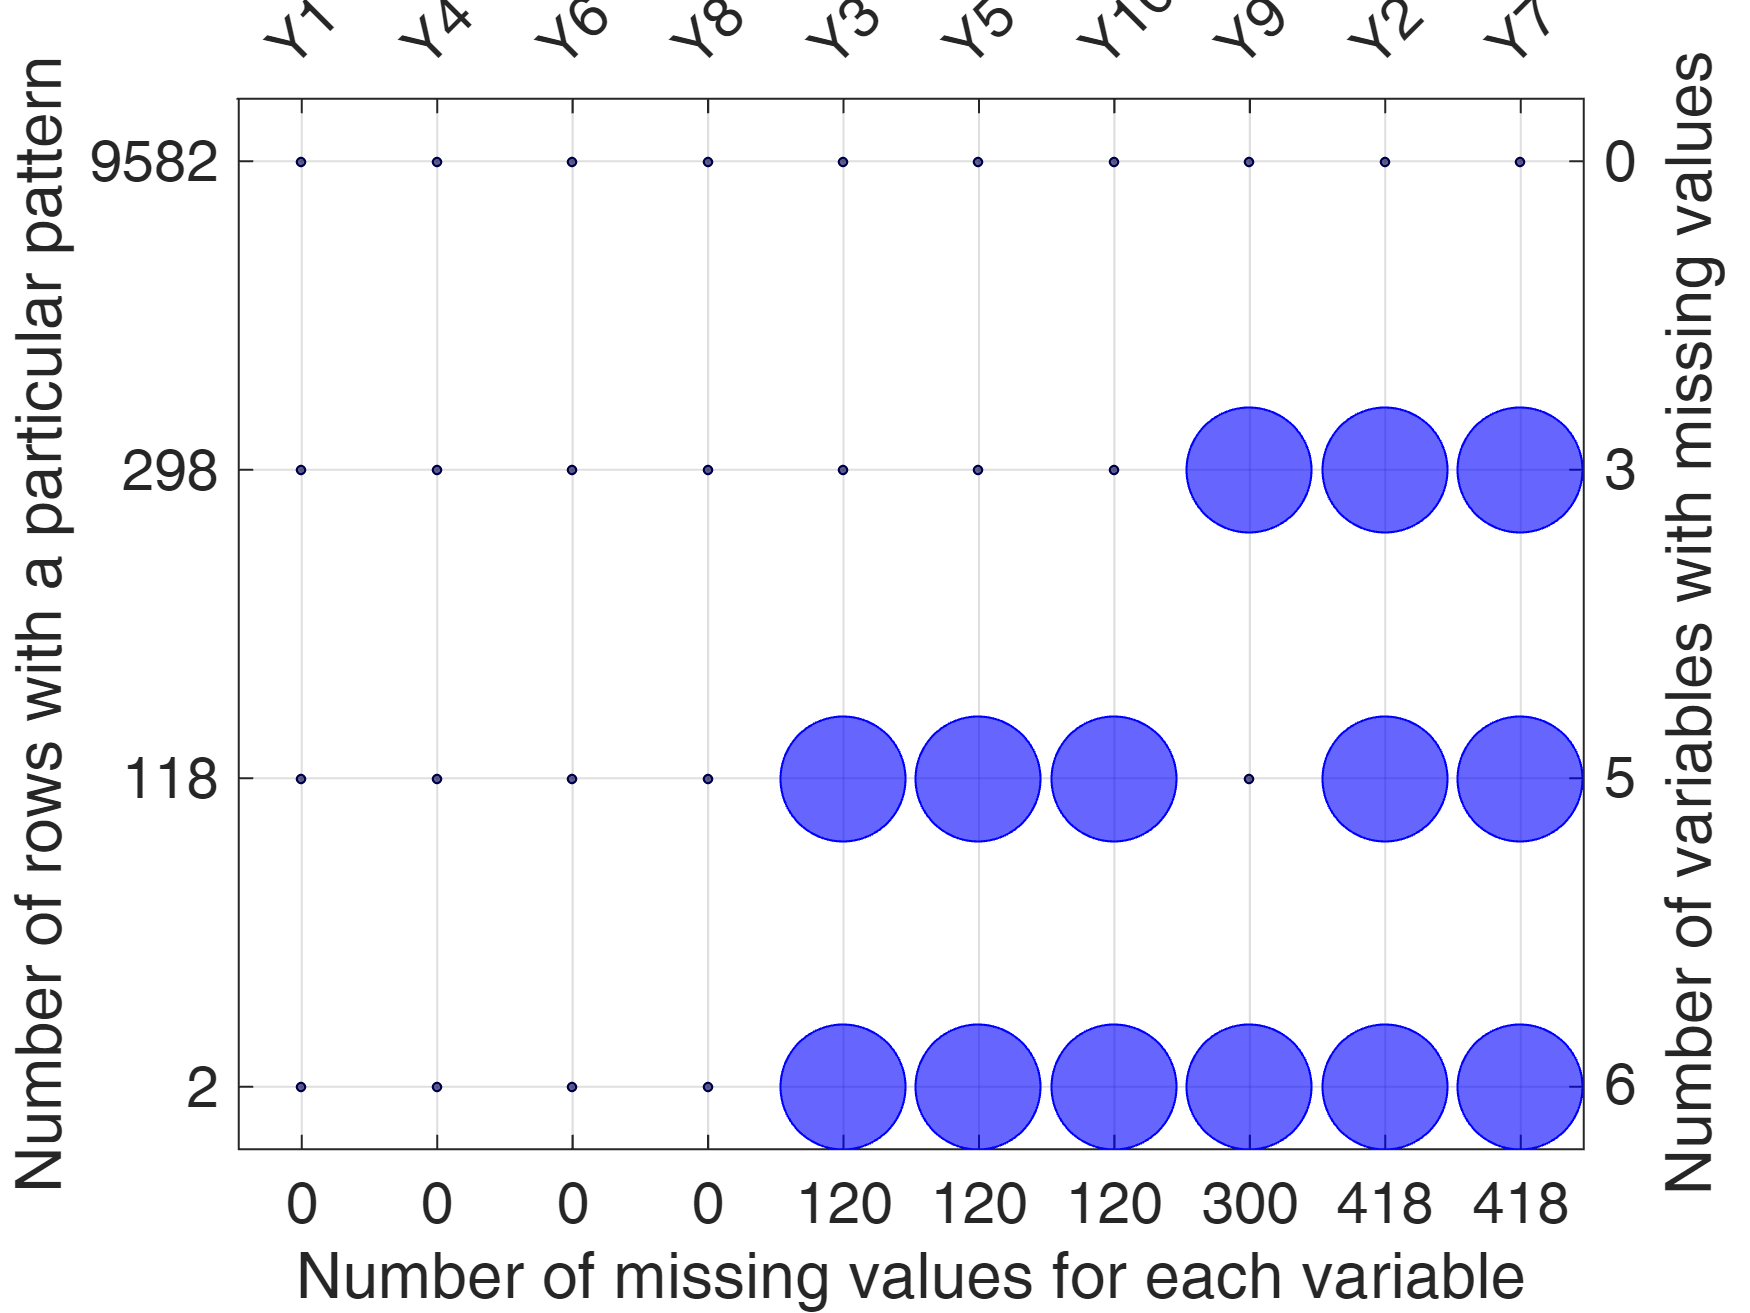

Detailed explanation of the "Missing data pattern figure"
Top axis contains the names of the variables.
Big circle means missing value; smaller filled dot represents non missing value.
Left axis shows the number of observations for each pattern
For example number 9582 shows that the associated pattern is repeated 9582 times.
The sum of the numbers on the left axis is n, the total number of rows.
Right axis counts the variables with missing values and
it is equal to the number of big circles in the corresponding row.
The number of missing values for each variable is shown on the bottom axis.


% Generate a matrix of size 10000-by-10 from N(0,1)
n=10000;
p=10;
X=randn(n,p);
% Create first missing  data pattern
n1=300; n2=3;
rowsWithMis=randsample(n,n1);
colsWithMis=randsample(p,n2);
X(rowsWithMis,colsWithMis)=NaN;
% Create second missing  data pattern
n1=120; n2=5;
rowsWithMis=randsample(n,n1);
colsWithMis=randsample(p,n2);
X(rowsWithMis,colsWithMis)=NaN;
[Mispat,tMisAndOut]=mdpattern(X);

The first output contains the details of the missing data pattern

` Mispat `is a table with size (*k*+1)x(*v*+2), where k is the total number of missing values patterns which are present in the data matrix and *v* is the number of variables with missing values. The first *k* rows contain the patterns.  The last row contains n (number of rows of the original dataset) and then the total number of  missing values in each column. The first column (named `NrowsWithPattern`) contains information about the number of observations for each pattern. The last column (named `NvarWithMis`) contains the number of variables with missing values for each pattern.

The columns of `Mispat` are sorted in non decreasing number of outliers. 

disp(Mispat)

                   NrowsWithPattern    Y1    Y4    Y6    Y8    Y3     Y5     Y10    Y9     Y2     Y7     NvarWithMis
                   ________________    __    __    __    __    ___    ___    ___    ___    ___    ___    ___________

    Pattern1             9582          1     1     1     1       1      1      1      1      1      1          0    
    Pattern2              298          1     1     1     1       1      1      1      0      0      0          3    
    Pattern3              118          1     1     1     1       0      

The second output contains the details of exploratory data analysis applied to each column with the number of univariate outliers (lower and upper).

`tMisAndOut` is a table of size *p*-by-8 where *p* is the number of variables of the original dataset which contains informations about missing values and univariate outliers for each variable. The rows of this table are associated with the variables. The columns are referred to a series of statistics.

More precisely:

Columns 1:4 contain mean and median, std deviation and rescaled MAD (normalized median absolute deviation).

Fifth column (`Count_miss`) contains the number of missing values for each variable.

Sixth column (`Perc_miss`) contains the percentage of missing data for each variable.

Seventh and eight columns (`outInf` and `outSup`)  contain the number of outliers respectively in the left and right tail of the distribution. The criterion to decide whether a unit is outlier is based on the boxplot concept, that is the outliers are the units which are above x0.75+1.5**IQR* or below x0.25-1.5**IQR*, where *IQR* is the interquartile range.

disp(tMisAndOut)

              Mean        Median       Stdev       MAD      Count_miss    Perc_miss    outInf    outSup
           __________    _________    _______    _______    __________    _________    ______    ______

    Y1      -0.011523    -0.022451     1.0049    0.99688         0             0         29        35  
    Y2       0.014287     0.010699     1.0025     1.0133       418          4.18         25        32  
    Y3       0.012158     0.011246    0.99683    0.99506       120           1.2         33        30  
    Y4       0.010638      0.02355    0.99609     1.0016         0             0         29        30  
    Y5     -0.0086

More on function mdpattern is in [http://rosa.unipr.it/FSDA/mdpattern.html](http://rosa.unipr.it/FSDA/mdpattern.html)

#### References

Schafer, J.L. (1997), Analysis of multivariate incomplete data. London: Chapman&Hall.

van Buuren S, Groothuis-Oudshoorn K (2011). “mice: Multivariate Imputation by Chained Equations in R.” *Journal of Statistical Software*, **45**(3), 1-67. [doi:10.18637/jss.v045.i03](https://doi.org/10.18637/jss.v045.i03).